clear

subject.testNr = '0';
f2aim = [500:500:1500 2000:1000:10000].';

f2IdxSuper{1} = [2 ; 4 ; 5 ; 6 ; 7 ; 8]; % 6 frequency standard DPOAE
f2IdxSuper{2} = [1 ; 2 ; 3; 4 ; 5 ; 6 ; 7 ; 8 ; 9 ; 10 ; 11 ;12]; % 12 frequency standard DPOAE

f2IdxSuper{3} = [2 6; 5 8; 4 7]; % 6 frequency manual minimum octave spacing 
f2IdxSuper{4} = [1 4 7 12 ; 2 5 9 0 ; 3 6 11 0 ; 8 0 0 0 ; 10 0 0 0]; % 12 frequency minimum manual octave spacing 

f2IdxSuper{5} = [2 8 ; 4 0 ; 5 0 ; 6 0 ; 7 0]; %6 frequency algorithm based spacing
f2IdxSuper{6} = [9 0 ; 4 10 ; 7 0 ; 11 0 ; 3 12 ; 5 0 ; 1 8 ; 2 6]; %12 frequency algorithm based spacing

f2IdxSuper{7} = [2 4 6 ; 5 8 0 ; 7 0 0]; %6 frequency relaxed algorithm based spacing
f2IdxSuper{8} = [7 12 0 ; 3 5 8 ; 2 6 11 ; 4 10 0 ; 1 9 0]; %6 frequency relaxed algorithm based spacing
% f2Idx = [2 4 6; 3 5 8; 1 7 12; 10 0 0];

subject.folderLocation = ['Measurement/testPerson_' subject.testNr];
mkdir(subject.folderLocation)

% Right ear

subject.ear = ['tp_' subject.testNr '_right'];
mkdir([subject.folderLocation '/' subject.ear]);

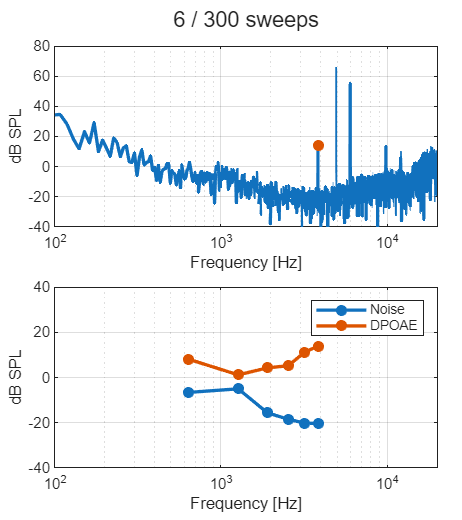

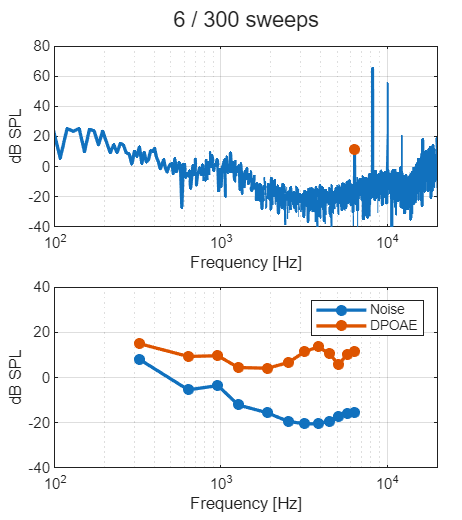

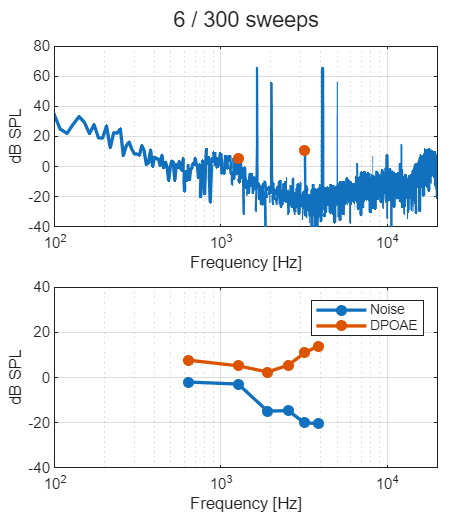

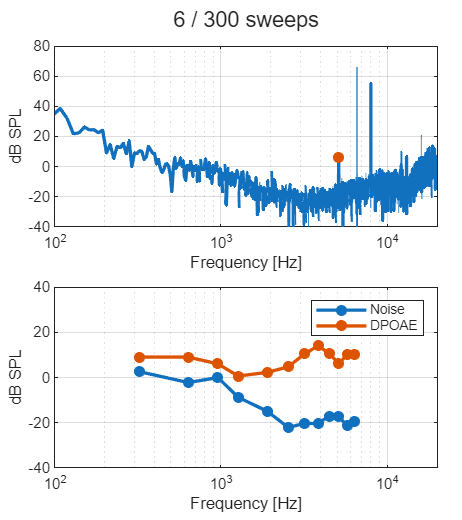

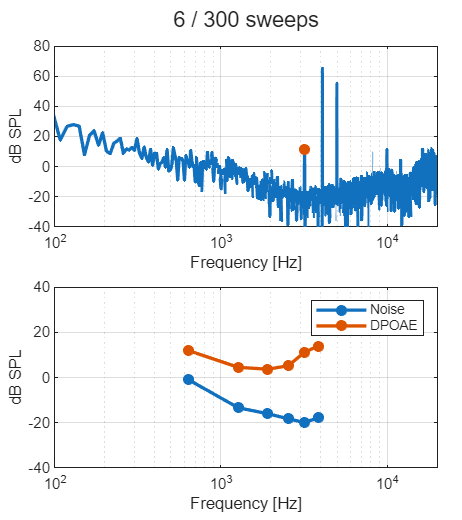

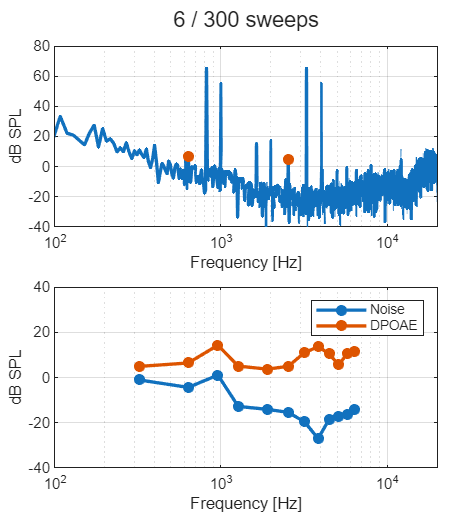

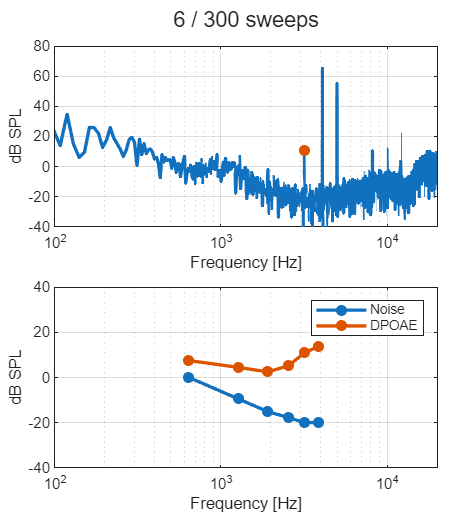

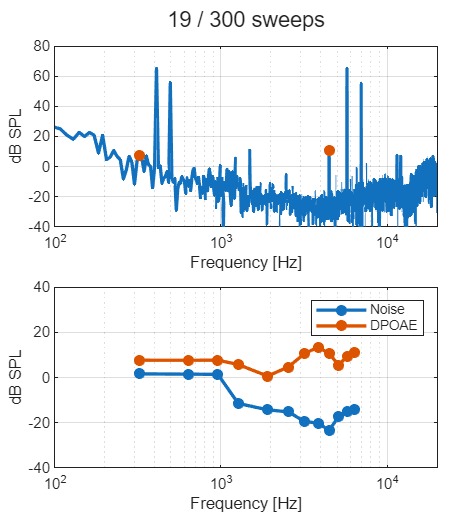


numRecs = length(f2IdxSuper);
measurementTimeMatrix = zeros(numRecs, 2);
for k = 1:numRecs
    f2Idx = f2IdxSuper{k};
    save("dpFrequenciesDummy.mat", "f2aim", "f2Idx");
    measMFDPOA;
    measurementTimeMatrix(k, 1) = measurementTime;
    clearvars -except f2IdxSuper f2aim numRecs measurementTimeMatrix subject
end

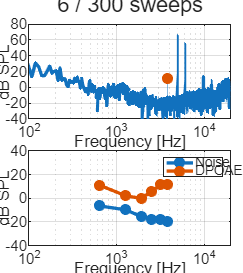

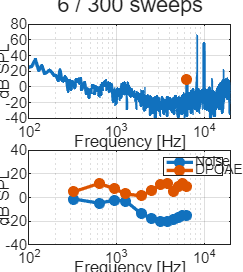

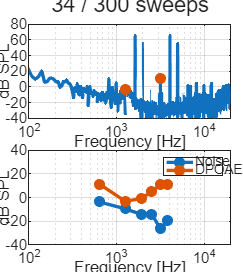

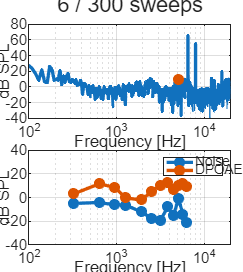

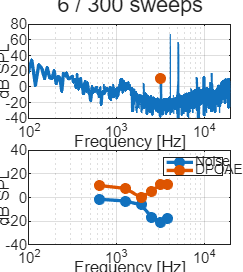

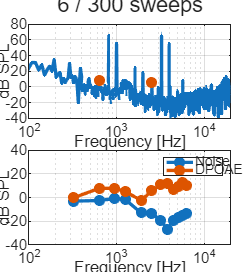

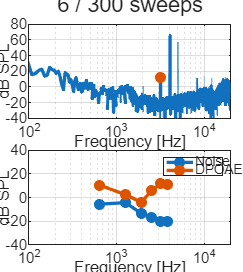

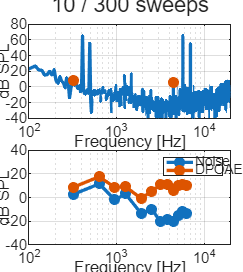

% Left ear

subject.ear = ['tp_' subject.testNr '_left'];
mkdir([subject.folderLocation '/' subject.ear]);

numRecs = length(f2IdxSuper);
measurementTimeMatrix = zeros(numRecs, 2);
for k = 1:numRecs
    f2Idx = f2IdxSuper{k};
    save("dpFrequenciesDummy.mat", "f2aim", "f2Idx");
    measMFDPOA;
    measurementTimeMatrix(k, 1) = measurementTime;
    clearvars -except f2IdxSuper f2aim numRecs measurementTimeMatrix subject
end


save([subject.folderLocation '/measurementTimes'], "measurementTimeMatrix");